Configuración

filename = 'identificacion_motor.csv';  % ajusta nombre
Ts = 0.01;     % tiempo de muestreo nominal en s (ej. 0.01=10ms)
save_plots_folder = 'resultados';

if ~exist(save_plots_folder,'dir'), mkdir(save_plots_folder); end

Caraga de archivos

T = readtable(filename);
t_cmd = T.t_cmd - T.t_cmd(1);
t_odom = T.t_odom - T.t_odom(1);
u = T.u_right;      % entrada (usa u_left si necesitas otro)
y = T.w_right;      % salida

Procesamiento de datos

%% --- CLEAN: eliminar NaN/Inf y duplicados ---
valid = isfinite(t_cmd) & isfinite(t_odom) & isfinite(u) & isfinite(y);
t_cmd = t_cmd(valid); t_odom = t_odom(valid); u = u(valid); y = y(valid);

[t_cmd, ia] = unique(t_cmd, 'stable'); u = u(ia);
[t_odom, ib] = unique(t_odom, 'stable'); y = y(ib);

%% --- SYNCHRONIZE: construir malla uniforme o usar t_cmd ---
% Opción 1: usar t_common = t_cmd (si t_cmd uniforme o cercano)
t_common = t_cmd;
y_sync = interp1(t_odom, y, t_common, 'linear', 'extrap');

% Si prefieres malla uniforme:
% t_common = t_cmd(1):Ts:t_cmd(end);
% u_common = interp1(t_cmd, u, t_common, 'previous','extrap'); % hold input
% y_sync = interp1(t_odom, y, t_common, 'linear','extrap');

Figuras

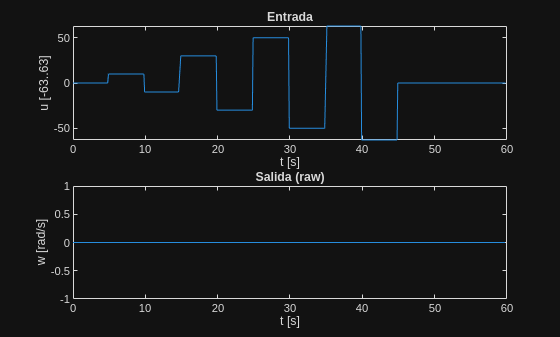

%% --- PLOT raw signals ---
figure; subplot(2,1,1); plot(t_cmd, u); xlabel('t [s]'); ylabel('u [-63..63]'); title('Entrada');
subplot(2,1,2); plot(t_odom, y); xlabel('t [s]'); ylabel('w [rad/s]'); title('Salida (raw)');
saveas(gcf, fullfile(save_plots_folder,'raw_signals.png'));

Modelamiento de la planta

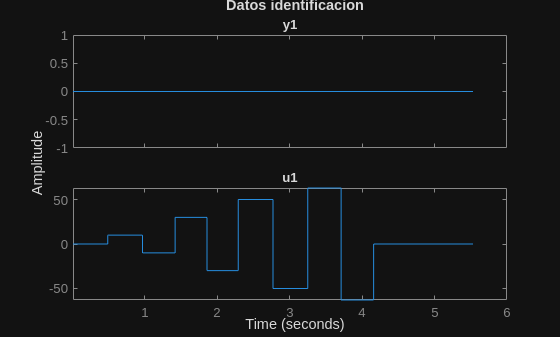

%% --- iddata ---
data_id = iddata(y_sync(:), u(:), Ts);  % y,u should be column vectors

figure; plot(data_id); title('Datos identificacion');
saveas(gcf, fullfile(save_plots_folder,'data_id.png'));


%% --- Estimate delay (optional) ---
% Estimar retardo con correlación cruzada
[XC, lags] = xcorr(y_sync - mean(y_sync), u - mean(u), 200, 'coeff');
[~, iMax] = max(XC);
lag_samples = lags(iMax);
delay_est = lag_samples * Ts;
fprintf('Delay estimate = %.4f s (lag = %d samples)\n', delay_est, lag_samples);

Delay estimate = -2.0000 s (lag = -200 samples)



%% --- Model estimation: probar varios metodos/ordenes ---
% ARX (orden 2)
na = 2; nb = 2; nk = max(0, round(delay_est/Ts)); % nk = delay en muestras
model_arx = arx(data_id, [na nb nk]);


% OE / TFEST (prueba 1er u 2do orden)
sys_tf1 = tfest(data_id, 1, nk);   % 1 pole, include nk delay
sys_tf2 = tfest(data_id, 2, nk);   % 2 poles

Comparativa de modelos

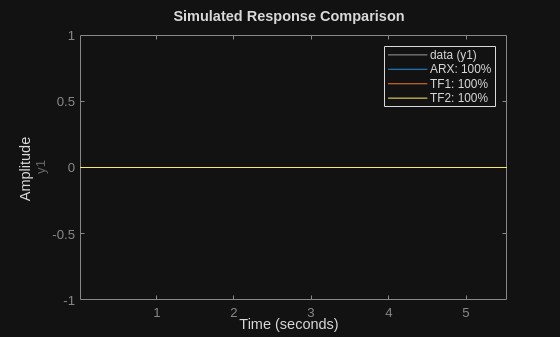

% Comparar ajustes
figure; compare(data_id, model_arx, sys_tf1, sys_tf2);
legend('data','ARX','TF1','TF2');
saveas(gcf, fullfile(save_plots_folder,'compare_models.png'));


% Extraer fit %
[~, y_arx] = compare(data_id, model_arx);
fit_arx = 100*(1 - norm(y_sync - y_arx.OutputData)/norm(y_sync - mean(y_sync)));

Dot indexing is not supported for variables of this type.

fprintf('Fit ARX: %.2f %%\n', fit_arx);

[~, y_tf2] = compare(data_id, sys_tf2);
fit_tf2 = 100*(1 - norm(y_sync - y_tf2.OutputData)/norm(y_sync - mean(y_sync)));
fprintf('Fit TF2: %.2f %%\n', fit_tf2);

%% --- Select model (ejemplo sys_tf2) ---
sysz = sys_tf2;  % si tfest devuelve discreto con Ts, está listo; si continuo -> c2d
if sysz.Ts == 0
    sysz = c2d(sysz, Ts, 'zoh');
end

% Parametros del modelo (numerador/denominador)
[numz, denz] = tfdata(sysz, 'v');
fprintf('G(z) = (%g z^0 + ...)/(%g z^2 + %g z + %g)\n', numz, denz(1), denz(2), denz(3));

%% --- Poles, zeros, bode ---
figure; zplane(numz, denz); title('Polos y ceros en z'); saveas(gcf, fullfile(save_plots_folder,'pz.png'));
figure; bode(sysz); title('Bode discreto'); saveas(gcf, fullfile(save_plots_folder,'bode.png'));

%% --- Residuals ---
figure; resid(data_id, sysz); title('Residuales'); saveas(gcf, fullfile(save_plots_folder,'resid.png'));

%% --- Step response (modelo) y comparativa con un step real (si tienes datos) ---
figure; step(sysz); title('Step response modelo'); saveas(gcf, fullfile(save_plots_folder,'step_model.png'));

% Si tienes un segmento real de step en y_sync con su entrada:
% identificamos indices donde u cambió de base a un valor y comparamos salida real vs model step (omito por simplicidad)

%% --- PID design (discrete) con pidtune ---
C = pidtune(sysz, 'PIDF');   % 'PID' o 'PIDF' (PID con filtro deriv)
Kp = C.Kp; Ki = C.Ki; Kd = C.Kd;
fprintf('PID gains: Kp=%.4f, Ki=%.4f, Kd=%.4f\n', Kp, Ki, Kd);

%% --- Simulate closed-loop ---
L = series(C, sysz);
Tcl = feedback(L, 1);
figure; step(Tcl); title('Lazo cerrado con PID'); saveas(gcf, fullfile(save_plots_folder,'step_closed.png'));

S = stepinfo(Tcl);
disp(S);  % contiene RiseTime, SettlingTime, Overshoot, etc.

%% --- Export gains for implementation (discrete) ---
% Si C es discreto, puedes extraer la forma que implementes. Si es continuo, discretiza:
if C.Ts == 0
    Cz = c2d(C, Ts, 'tustin');
else
    Cz = C;
end
% extraer coeficientes del Cz en forma directa si te interesa (uso interno de MATLAB)
